clear all
close all
L_test1 = [128 612.7 571.6 115.7];

q_test0 = [0 0 0 0 0 0];
q_test1 = [pi/2 0 0 0 0 0];
q_test2 = [pi/4 pi/2 pi/2  pi/2 pi/2 pi/2];
q_test3 = [0 0.2 0.5 1 0.5 1];

fk=FK(q_test0,L_test1)

fk =    1.0e+03 *

    0.0010         0         0         0
         0    0.0010         0         0
         0         0    0.0010    1.4280
         0         0         0    0.0010


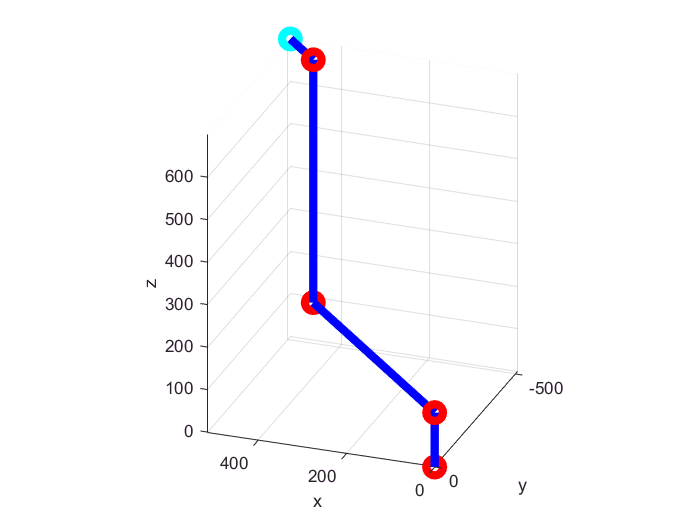

figure;
hold on
view(200,25)
grid on
axis equal
draw_robot(q_test2,L_test1,'-b')

syms q1_symb q2_symb q3_symb q4_symb q5_symb q6_symb q7_symb real
syms d1_symb d2_symb d3_symb d4_symb d5_symb d6_symb d7_symb real

q_symb=[q1_symb q2_symb q3_symb q4_symb q5_symb q6_symb q7_symb];
L_symb=[d1_symb d2_symb d3_symb d4_symb d5_symb d6_symb d7_symb];
%Jq=simplify(Jacobian(q_symb,L_symb))

%Jacobbian
Jq1=Jacobian(q_test1,L_test1)

Jq1 =    1.0e+03 *

         0    0.0000    0.0000    0.0000         0         0
         0    1.3000    0.6873    0.1157         0         0
         0         0         0         0         0         0
         0   -0.0010   -0.0010   -0.0010         0   -0.0010
         0    0.0000    0.0000    0.0000         0    0.0000
    0.0010         0         0         0    0.0010         0


**Weighted Seudo-Inverse**  



%Input: target position and orientation we want,  positions, lenghts of links

pc_target=[800; 400; 800]

pc_target =    800
   400
   800



%Weighted Pseudo Inverser 
q_ik_pseudoInverse_weighted = IK_JacobbianWeighted(pc_target, q_test1, L_test1)

q_ik_pseudoInverse_weighted =    1.0e+03 *

    0.0020
    0.0010
    0.0004
    0.0022
    0.0009
    9.1386


p_ik_pseudoInverse_weighted = FK(q_ik_pseudoInverse_weighted,L_test1);
pc_ik_pseudoInverse_weighted=p_ik_pseudoInverse_weighted(1:3, 4)

pc_ik_pseudoInverse_weighted =   800.0000
  400.0000
  800.0000


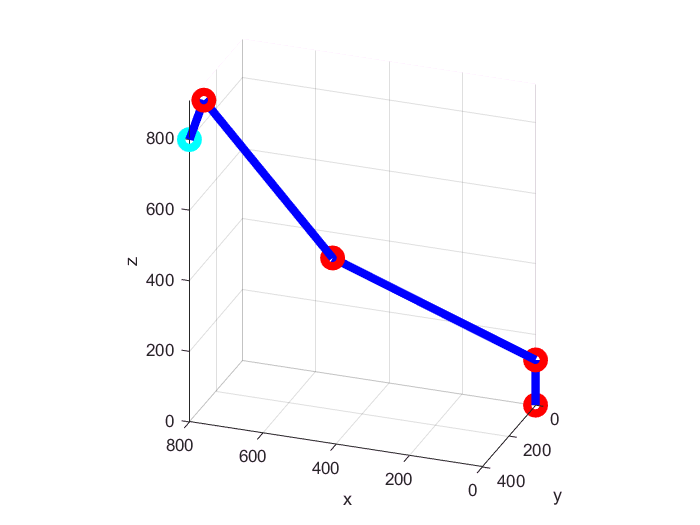



%draw target position, position using  weighted pseudo inverse and Damped Least Squares
figure;
hold on
view(200,25)
grid on
axis equal
draw_robot(q_ik_pseudoInverse_weighted,L_test1,'-b')

**Damped Least Squares**

pc_target=[800; 400; 800]

pc_target =    800
   400
   800



%Damped Least Squares
q_ik_Damped_Least_Squares = IK_JacobbianDampedLeast(pc_target, q_test0, L_test1) 

q_ik_Damped_Least_Squares =     2.0344
    1.0364
    0.4266
    2.1807
   -0.1828
  -54.2640


p_ik_Damped_Least_Squares = FK(q_ik_Damped_Least_Squares,L_test1);
pc_ik_Damped_Least_Squares=p_ik_Damped_Least_Squares(1:3, 4)

pc_ik_Damped_Least_Squares =   800.0000
  400.0000
  800.0000


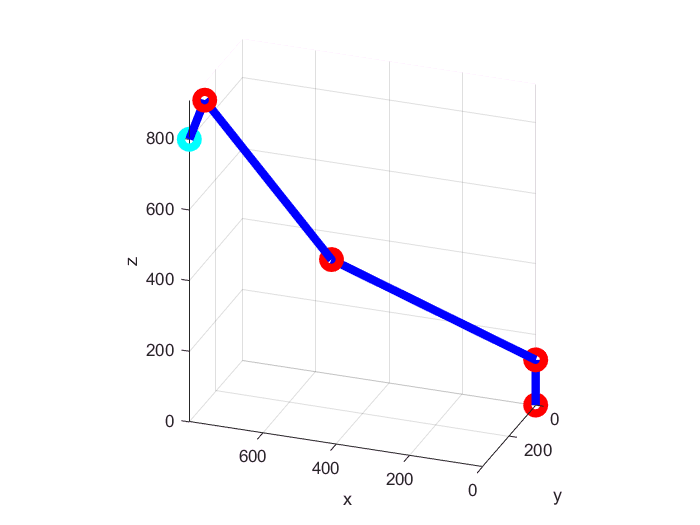


figure;
hold on
view(200,25)
grid on
axis equal
draw_robot(q_ik_Damped_Least_Squares,L_test1,'-b')

**Null-space methods**  


pc_target=[600; 900; 400]

pc_target =    800
   400
   800



%Null Space 
q_ik_Null_Space  = IK_NullSpace(pc_target, q_test3, L_test1) 

q_ik_Null_Space =    -1.1071
   -0.7038
    0.6768
    1.9600
    0.5179
    1.1032


p_ik_Null_Space = FK(q_ik_Null_Space,L_test1);
pc_ik_Null_Space=p_ik_Null_Space(1:3, 4)

pc_ik_Null_Space =   800.0000
  400.0000
  800.0000


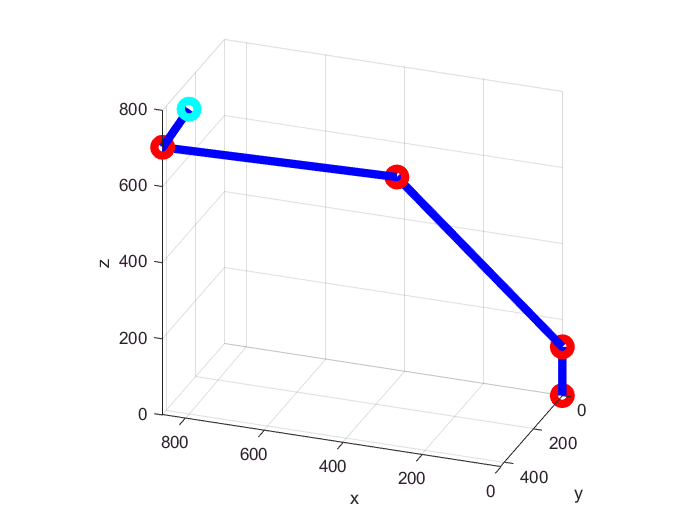


figure;
hold on
view(200,25)
grid on
axis equal
draw_robot(q_ik_Null_Space,L_test1,'-b')